# Calculus 1

Find the minimum of a function... Using MATLAB Symbolic Toolbox

% Define symbolic variable
syms x

% Define symbolic function
f = 2*x^2+3*x+1

$$f = 2\,x^{2}+3\,x+1$$

Plot using special plot tool that works with **Symbolic Functions**

fplot(f,[-2,2])
hold on

To compute the maximum and minima we wish to solve


$$g\left(x\right)=\frac{\textrm{df}}{\textrm{dx}}=0$$


% Compute the derivative
g = diff(f)

$$g = 4\,x+3$$

% Set it to zero
xMin = solve(g==0)

$$xMin = -\frac{3}{4}$$

We now find the value 


$$f_{\min } =f\left(x_{\min } \right)$$


and plot it as a red asterisk over the existing plot

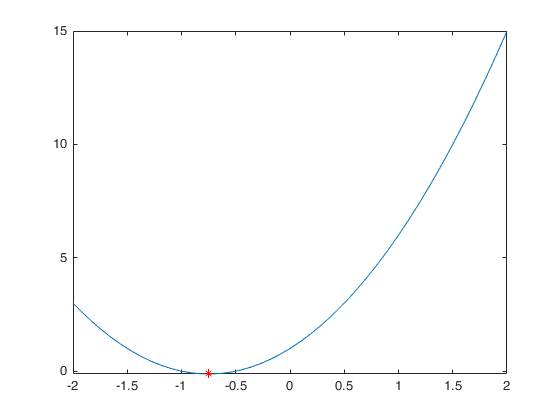

fMin = subs(f,x,xMin);

plot(xMin,fMin,'*r')

# Wheatstone Bridge

See Week 2 Ex 3 for illustration

syms I1 I2 I3 I4
syms R1 R2 R3 R4
syms Vs Vg

I1 = solve(I1==I2,I1);
I3 = solve(I3==I4,I3);
I2 = solve(R1*I1+R2*I2 == Vs,I2);
I4 = solve(R3*I3+R4*I4 == Vs,I4);

Vg = solve(R2*I2-R4*I4 == Vg,Vg)

$$Vg = \frac{R_{2}\,\mathrm{Vs}}{R_{1}+R_{2}}-\frac{R_{4}\,\mathrm{Vs}}{R_{3}+R_{4}}$$


Vg = collect(Vg,Vs)

$$Vg = \left(\frac{R_{2}}{R_{1}+R_{2}}-\frac{R_{4}}{R_{3}+R_{4}}\right)\,\mathrm{Vs}$$

Now we see how different changes in the resistances affect $V_g$

% Case 1: All Resistances are equal
syms R

Vg1 = subs(Vg,[R1 R2 R3 R4],[R R R R])

$$Vg1 = 0$$


% Case 2: R1 = R+DR, all others stay the same
syms DR

Vg2 = subs(Vg,[R1 R2 R3 R4],[R+DR R R R])

$$Vg2 = \mathrm{Vs}\,\left(\frac{R}{\mathrm{DR}+2\,R}-\frac{1}{2}\right)$$

% Use simplify to make equations easier to read
Vg2 = simplify(Vg2)

$$Vg2 = -\frac{\mathrm{DR}\,\mathrm{Vs}}{2\,\mathrm{DR}+4\,R}$$


% Case 3: R1 = R-DR, R2 = R+DR, the other two stay the same
Vg3 = simplify(subs(Vg,[R1 R2 R3 R4],[R-DR R+DR R R]))

$$Vg3 = \frac{\mathrm{DR}\,\mathrm{Vs}}{2\,R}$$